# Double Pendulum simulation

## 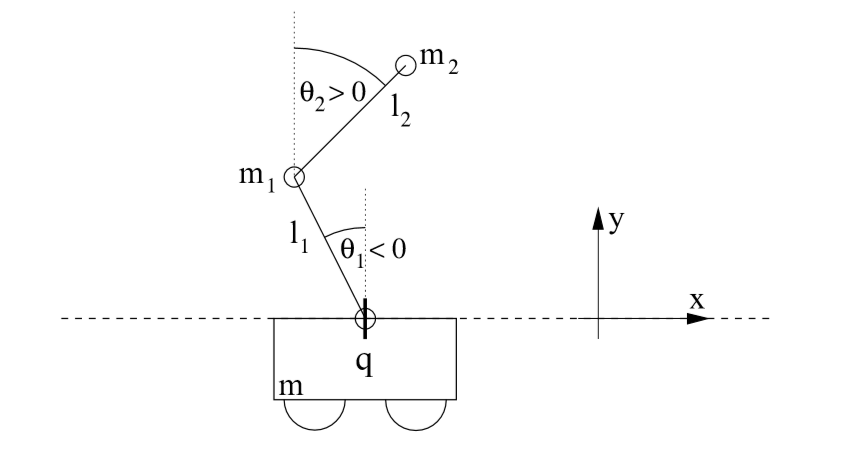

## Equations of Motion - Hand Derived

### Kinematic Constraints

$x_q = q$, $x_1 = x_q + l_1 \sin(\theta_1) $, $x_2 = x_1 + l_2 \sin(\theta_2)$

$y_q = 0$, $y_1 = y_q + l_1 \cos(\theta_1)$, $y_2 = y_2 + l_2 \cos(\theta_2)$

% syms q l1 theta_1 l2 theta_2
% xq = q
% x1 = xq + l1*sin(theta_1)
% x2 = x1 + l2*sin(theta_2)
% yq = 0
% y1 = yq + l1*cos(theta_1)
% y2 = y1 + l2*cos(theta_2)
% 
% % derivatives
% syms q_dot theta_dot_1 theta_dot_2 
% xq_dot = q_dot;
% x1_dot = q_dot + l1*cos(theta_1)*theta_dot_1
% x2_dot = q_dot + l1*cos(theta_1)*theta_dot_1 + l2*cos(theta_2)*theta_dot_2
% yq_dot = 0
% y1_dot = -l1*sin(theta_1)*theta_dot_1
% y2_dot = -l1*sin(theta_1)*theta_dot_1 - l2*sin(theta_2)*theta_dot_2
% 
% % don't need 2nd derivative yet
% 

### Potential Energy


$$V = mgy_q + m_1 g y_1 + m_2 g y_2$$


% syms  m_q m1 m2 g
% V = m_q*g*yq + m1*g*y1 + m2*g*y2

### Kinetic Energy


$$K = \frac{1}{2} m_q (\dot{x_q}^2 + \dot{y_q}^2) + \frac{1}{2} m_1 (\dot{x_1}^2 + \dot{y_1}^2)  + \frac{1}{2} m_2 (\dot{x_2}^2 + \dot{y_2}^2)$$


% K = 1/2*(m_q*(xq_dot^2 + yq_dot^2) ...
%         + m1*(x1_dot^2 + y1_dot^2) ...
%         + m2*(x2_dot^2 + y2_dot^2) )

### Euler-Lagrange Equations

Lagrangian: $L = K - V$

Euler-Lagrange equations: $\frac{d}{dt}(\frac{\delta L}{\delta \dot{q_i}}) - \frac{\delta L}{\delta q_i} = Q_{i}$

where $Q_i$ represents the external (non-conservative) forces applied

% L = K - V
% dLdq_dot = collect(simplify(expand(diff(L,q_dot))),[q_dot theta_dot_1 theta_dot_2])
% dLdq = diff(L,q)
% syms q_ddot theta_ddot_1 theta_ddot_2
% Qq = (m_q + m1 + m2)*q_ddot + ...
%     + l1*m1*(theta_ddot_1*cos(theta_1) + theta_dot_1*(-sin(theta_1)*theta_dot_1)) ...
%     + l1*m2*(theta_ddot_1*cos(theta_1) + theta_dot_1*(-sin(theta_1)*theta_dot_1)) ...
%     + l2*m2*(theta_ddot_2*cos(theta_2) + theta_dot_2*(-sin(theta_2)*theta_dot_2));
% Qq = simplify(expand(Qq))
% 
% dLdtheta_dot_1 = collect(simplify(expand(diff(L,theta_dot_1))),[q_dot theta_dot_1 theta_dot_2])
% dLdtheta_dot_1_dt = q_ddot*l1*(m1*cos(theta_1) + m2*cos(theta_2)) ...
%                   + q_dot*l1*(m1*(-sin(theta_1)*theta_dot_1) + m2*(-sin(theta_2)*theta_dot_2)) ...
%                   + theta_ddot_1*(l1^2*(m1+m2)) ...
%                   + theta_ddot_2*l1*l2*m2*cos(theta_1-theta_2) ...
%                   + theta_dot_2*l1*l2*m2*(-sin(theta_1-theta_2)*(theta_dot_1 - theta_dot_2))
% 
% dLdtheta_1 = collect(simplify(expand(diff(L,theta_1))),[q_dot,theta_dot_1, theta_dot_2])
% Q1 = collect(simplify(expand(dLdtheta_dot_1_dt - dLdtheta_1)),[q_ddot, theta_ddot_1, theta_ddot_2, theta_dot_2,g])

## Equations of Motion - MATLAB Derived

### Kinematic Constraints

$x_q = q$, $x_1 = x_q + l_1 \sin(\theta_1) $, $x_2 = x_1 + l_2 \sin(\theta_2)$

$y_q = 0$, $y_1 = y_q + l_1 \cos(\theta_1)$, $y_2 = y_2 + l_2 \cos(\theta_2)$

syms q(t) l1 theta_1(t) l2 theta_2(t)
xq = q;
x1 = xq + l1*sin(theta_1);
x2 = x1 + l2*sin(theta_2);
yq = 0;
y1 = yq + l1*cos(theta_1);
y2 = y1 + l2*cos(theta_2);

% derivatives
xq_dot = diff(q,t)

$$xq\_dot(t) = \frac{\partial }{\partial t}q\left(t\right)$$

x1_dot = diff(x1,t)

$$x1\_dot(t) = \frac{\partial }{\partial t}q\left(t\right)+l_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)$$

x2_dot = diff(x2,t)

$$x2\_dot(t) = \frac{\partial }{\partial t}q\left(t\right)+l_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)+l_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)$$

yq_dot = 0

yq_dot = 0

y1_dot = diff(y1,t)

$$y1\_dot(t) = -l_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)$$

y2_dot = diff(y2,t)

$$y2\_dot(t) = -l_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)-l_{2}\,\sin\left(\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)$$

### Potential Energy


$$V = mgy_q + m_1 g y_1 + m_2 g y_2$$


syms  m_q m1 m2 g
V = m_q*g*yq + m1*g*y1 + m2*g*y2

$$V(t) = g\,m_{2}\,\left(l_{1}\,\cos\left(\theta_{1}\left(t\right)\right)+l_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\right)+g\,l_{1}\,m_{1}\,\cos\left(\theta_{1}\left(t\right)\right)$$

### Kinetic Energy


$$K = \frac{1}{2} m_q (\dot{x_q}^2 + \dot{y_q}^2) + \frac{1}{2} m_1 (\dot{x_1}^2 + \dot{y_1}^2)  + \frac{1}{2} m_2 (\dot{x_2}^2 + \dot{y_2}^2)$$


K = 1/2*(m_q*(xq_dot^2 + yq_dot^2) + m1*(x1_dot^2 + y1_dot^2) + m2*(x2_dot^2 + y2_dot^2))

$$K(t) = \begin{array}{l} \frac{m_{1}\,\left({\left(\frac{\partial }{\partial t}q\left(t\right)+\sigma_{1}\right)}^{2}+{l_{1}}^{2}\,{\sin\left(\theta_{1}\left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}\right)}{2}+\frac{m_{2}\,\left({\left(\frac{\partial }{\partial t}q\left(t\right)+\sigma_{1}+l_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}+{\left(l_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)+l_{2}\,\sin\left(\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}\right)}{2}+\frac{m_{q}\,{\left(\frac{\partial }{\partial t}q\left(t\right)\right)}^{2}}{2}\\ \mathrm{where}\\ \sigma_{1}=l_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right) \end{array}$$

From earlier manual deriviation,

K = $\frac{m_2 \,{\left({{\left(l_1 \,{\dot{\theta} }_1 \,\sin \left(\theta_1 \right)+l_2 \,{\dot{\theta} }_2 \,\sin \left(\theta_2 \right)\right)}}^2 +{{\left(\dot{q} +l_1 \,{\dot{\theta} }_1 \,\cos \left(\theta_1 \right)+l_2 \,{\dot{\theta} }_2 \,\cos \left(\theta_2 \right)\right)}}^2 \right)}}{2}+\frac{m_q \,{\dot{q} }^2 }{2}+\frac{m_1 \,{\left({{\left(\dot{q} +l_1 \,{\dot{\theta} }_1 \,\cos \left(\theta_1 \right)\right)}}^2 +{l_1 }^2 \,{{\dot{\theta} }_1 }^2 \,{\sin \left(\theta_1 \right)}^2 \right)}}{2}$

To check the that it matches: (it does)

% subs(K,[diff(q,t), diff(theta_1,t),diff(theta_2,t)],[q_dot, theta_dot_1, theta_dot_2])

### Euler-Lagrange Equations

Lagrangian: $L = K - V$

Euler-Lagrange equations: $\frac{d}{dt}(\frac{\delta L}{\delta \dot{q_i}}) - \frac{\delta L}{\delta q_i} = Q_{i}$

where $Q_i$ represents the external (non-conservative) forces applied

L = simplify(expand(K - V))

$$L(t) = \begin{array}{l} \frac{m_{1}\,\sigma_{1}}{2}+\frac{m_{2}\,\sigma_{1}}{2}+\frac{m_{q}\,\sigma_{1}}{2}+\frac{{l_{1}}^{2}\,m_{1}\,\sigma_{2}}{2}+\frac{{l_{1}}^{2}\,m_{2}\,\sigma_{2}}{2}+\frac{{l_{2}}^{2}\,m_{2}\,{\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}}{2}-g\,l_{1}\,m_{1}\,\cos\left(\theta_{1}\left(t\right)\right)-g\,l_{1}\,m_{2}\,\cos\left(\theta_{1}\left(t\right)\right)-g\,l_{2}\,m_{2}\,\cos\left(\theta_{2}\left(t\right)\right)+l_{1}\,m_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\,\frac{\partial }{\partial t}q\left(t\right)+l_{1}\,m_{2}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\,\frac{\partial }{\partial t}q\left(t\right)+l_{2}\,m_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\,\frac{\partial }{\partial t}q\left(t\right)+l_{1}\,l_{2}\,m_{2}\,\cos\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}q\left(t\right)\right)}^{2}\\ \sigma_{2}={\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2} \end{array}$$

#### Q0; q

dLdq_dot = collect(simplify(expand(diff(L,diff(q,t)))),[diff(q,t) diff(theta_1,t) diff(theta_2,t)]);
ddt_dLdq_dot = diff(dLdq_dot,t);
dLdq = diff(L,q);
Q0 = collect(simplify(expand(ddt_dLdq_dot - dLdq)),[diff(q,t,2), diff(theta_1,t,2), diff(theta_1,t), diff(theta_2,t,2), diff(theta_2,t)])

$$Q0(t) = \left(m_{1}+m_{2}+m_{q}\right)\,\frac{\partial^{2}}{\partial t^{2}}q\left(t\right)+\left(l_{1}\,m_{1}\,\cos\left(\theta_{1}\left(t\right)\right)+l_{1}\,m_{2}\,\cos\left(\theta_{1}\left(t\right)\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)+\left(-l_{1}\,m_{1}\,\sin\left(\theta_{1}\left(t\right)\right)-l_{1}\,m_{2}\,\sin\left(\theta_{1}\left(t\right)\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}+\left(l_{2}\,m_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)+\left(-l_{2}\,m_{2}\,\sin\left(\theta_{2}\left(t\right)\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}$$

NOTE that the above equation matches the reference document, downloaded from... 

[https://www3.math.tu-berlin.de/Vorlesungen/SoSe12/Kontrolltheorie/matlab/inverted_pendulum.pdf](https://www3.math.tu-berlin.de/Vorlesungen/SoSe12/Kontrolltheorie/matlab/inverted_pendulum.pdf)

accessed on 10/29/2022

#### Q1: $\theta_1$

dLdtheta_1_dot = collect(simplify(expand(diff(L,diff(theta_1,t)))),[diff(q,t) diff(theta_1,t) diff(theta_2,t)]);
ddt_dLdtheta_1_dot = diff(dLdtheta_1_dot,t);
dLdtheta_1 = diff(L,theta_1);
Q1 = collect(simplify(expand(ddt_dLdtheta_1_dot - dLdtheta_1)),[diff(q,t,2), diff(theta_1,t,2), diff(theta_1,t), diff(theta_2,t,2), diff(theta_2,t)])

$$Q1(t) = \begin{array}{l} \left(l_{1}\,m_{1}\,\cos\left(\theta_{1}\left(t\right)\right)+l_{1}\,m_{2}\,\cos\left(\theta_{1}\left(t\right)\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}q\left(t\right)+\left({l_{1}}^{2}\,m_{1}+{l_{1}}^{2}\,m_{2}\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)+\left(l_{1}\,l_{2}\,m_{2}\,\cos\left(\sigma_{1}\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)+\left(l_{1}\,l_{2}\,m_{2}\,\sin\left(\sigma_{1}\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}-g\,l_{1}\,m_{1}\,\sin\left(\theta_{1}\left(t\right)\right)-g\,l_{1}\,m_{2}\,\sin\left(\theta_{1}\left(t\right)\right)\\ \mathrm{where}\\ \sigma_{1}=\theta_{1}\left(t\right)-\theta_{2}\left(t\right) \end{array}$$

#### Q2: $\theta_2$

dLdtheta_2_dot = collect(simplify(expand(diff(L,diff(theta_2,t)))),[diff(q,t) diff(theta_1,t) diff(theta_2,t)]);
ddt_dLdtheta_2_dot = diff(dLdtheta_2_dot,t);
dLdtheta_2 = diff(L,theta_2);
Q2 = collect(simplify(expand(ddt_dLdtheta_2_dot - dLdtheta_2)),[diff(q,t,2), diff(theta_1,t,2), diff(theta_1,t), diff(theta_2,t,2), diff(theta_2,t)])

$$Q2(t) = \begin{array}{l} \left(l_{2}\,m_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}q\left(t\right)+\left(l_{1}\,l_{2}\,m_{2}\,\cos\left(\sigma_{1}\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)+\left(-l_{1}\,l_{2}\,m_{2}\,\sin\left(\sigma_{1}\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}+\left({l_{2}}^{2}\,m_{2}\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)-g\,l_{2}\,m_{2}\,\sin\left(\theta_{2}\left(t\right)\right)\\ \mathrm{where}\\ \sigma_{1}=\theta_{1}\left(t\right)-\theta_{2}\left(t\right) \end{array}$$

### Euler-Lagrange with Non-Conservative Forces

assume there is a disturbance, w and a frictional damping force $-d\dot{q_i}$ at each node; the cart, m1 and m2

Additionally there is an external force u applied to cart, that is our control input:


$$Q_q = Q_0 = u + w_0 - d_0 \dot{q}$$



$$Q_1 = w_1 -d_1 \dot{\theta_1}$$



$$Q_2 = w_2 -d_2 \dot{\theta_2}$$


syms u w0 d0 w1 d1 w2 d2
syms q_ddot theta_ddot_1 theta_ddot_2 % creating symbolic variables for 2nd derivatives
eqn0 = subs(Q0 == u + w0 - d0*diff(q,t), [diff(q,t,2), diff(theta_1,t,2), diff(theta_2,t,2)], [q_ddot, theta_ddot_1, theta_ddot_2]);
eqn1 = subs(Q1 == w1 - d1*diff(theta_1,t), [diff(q,t,2), diff(theta_1,t,2), diff(theta_2,t,2)], [q_ddot, theta_ddot_1, theta_ddot_2]);
eqn2 = subs(Q2 == w2 - d2*diff(theta_2,t), [diff(q,t,2), diff(theta_1,t,2), diff(theta_2,t,2)], [q_ddot, theta_ddot_1, theta_ddot_2]);
sol = solve([eqn0, eqn1, eqn2],[q_ddot, theta_ddot_1, theta_ddot_2]);

## Setting up the State-Space equations

let $y = \pmatrix{q \cr \theta_1 \cr \theta_2}$ and $x = \pmatrix{y \cr \dot{y}}$

y_dot = [diff(q,t); diff(theta_1,t); diff(theta_2,t)];
y_ddot = [sol.q_ddot; sol.theta_ddot_1; sol.theta_ddot_2];
syms x0 x1 x2 x3 x4 x5
x_dot = subs(simplify(expand([y_dot; y_ddot])),[diff(q,t), diff(theta_1,t), diff(theta_2,t), q, theta_1, theta_2], [x3, x4, x5, x0, x1, x2]);
x_dot = x_dot(t)

symvar(x_dot)

$$ans = \left(\begin{array}{cccccccccccccccccc} d_{0} & d_{1} & d_{2} & g & l_{1} & l_{2} & m_{1} & m_{2} & m_{q} & u & w_{0} & w_{1} & w_{2} & x_{1} & x_{2} & x_{3} & x_{4} & x_{5} \end{array}\right)$$

### Linearize

In our simulation we will set w = 0 (no external disturbances)

x_dot_internal = subs(x_dot,[w0, w1, w2], [0 0 0]);
x = [x0; x1; x2; x3; x4; x5];
Asym = jacobian(x_dot_internal,x)

Bsym = jacobian(x_dot_internal,u)

$$Bsym = \begin{array}{l} \left(\begin{array}{c} 0\\ 0\\ 0\\ \frac{2\,l_{1}\,l_{2}\,m_{1}+l_{1}\,l_{2}\,m_{2}-l_{1}\,l_{2}\,m_{2}\,\sigma_{3}}{l_{1}\,l_{2}\,\sigma_{2}}\\ -\frac{2\,l_{1}\,l_{2}\,m_{1}\,\cos\left(x_{1}\right)+l_{1}\,l_{2}\,m_{2}\,\cos\left(x_{1}\right)-l_{1}\,l_{2}\,m_{2}\,\cos\left(x_{1}-2\,x_{2}\right)}{{l_{1}}^{2}\,l_{2}\,\sigma_{2}}\\ \frac{l_{1}\,l_{2}\,{m_{2}}^{2}\,\sigma_{1}-l_{1}\,l_{2}\,{m_{2}}^{2}\,\cos\left(x_{2}\right)+l_{1}\,l_{2}\,m_{1}\,m_{2}\,\sigma_{1}-l_{1}\,l_{2}\,m_{1}\,m_{2}\,\cos\left(x_{2}\right)}{l_{1}\,{l_{2}}^{2}\,m_{2}\,\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(2\,x_{1}-x_{2}\right)\\ \sigma_{2}=m_{1}\,m_{2}+2\,m_{1}\,m_{q}+m_{2}\,m_{q}-{m_{1}}^{2}\,\cos\left(2\,x_{1}\right)+{m_{1}}^{2}-m_{1}\,m_{2}\,\cos\left(2\,x_{1}\right)-m_{2}\,m_{q}\,\sigma_{3}\\ \sigma_{3}=\cos\left(2\,x_{1}-2\,x_{2}\right) \end{array}$$

#### Setting equilibrium point to [0; 0; 0; 0; 0; 0]

A0 = simplify(subs(Asym,x,zeros(6,1)))

$$A0 = \begin{array}{l} \left(\begin{array}{cccccc} 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ 0 & -\frac{g\,\left(m_{1}+m_{2}\right)}{m_{q}} & 0 & -\frac{d_{0}}{m_{q}} & \frac{d_{1}}{l_{1}\,m_{q}} & 0\\ 0 & \frac{g\,\left(m_{1}+m_{2}\right)\,\left(m_{1}+m_{q}\right)}{l_{1}\,m_{1}\,m_{q}} & -\frac{g\,m_{2}}{l_{1}\,m_{1}} & \frac{d_{0}}{l_{1}\,m_{q}} & -\frac{d_{1}\,\left(m_{1}+m_{q}\right)}{{l_{1}}^{2}\,m_{1}\,m_{q}} & \frac{d_{2}}{l_{1}\,l_{2}\,m_{1}}\\ 0 & -\sigma_{1} & \sigma_{1} & 0 & \frac{d_{1}}{l_{1}\,l_{2}\,m_{1}} & -\frac{d_{2}\,\left(m_{1}+m_{2}\right)}{{l_{2}}^{2}\,m_{1}\,m_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{g\,\left(m_{1}+m_{2}\right)}{l_{2}\,m_{1}} \end{array}$$

B0 = simplify(subs(Bsym,x,zeros(6,1)))

$$B0 = \left(\begin{array}{c} 0\\ 0\\ 0\\ \frac{1}{m_{q}}\\ -\frac{1}{l_{1}\,m_{q}}\\ 0 \end{array}\right)$$

### Subbing in Some real values to aid in simulation

vars = symvar(A0+B0)

$$vars = \left(\begin{array}{ccccccccc} d_{0} & d_{1} & d_{2} & g & l_{1} & l_{2} & m_{1} & m_{2} & m_{q} \end{array}\right)$$

% [1/s] friction damping coefficient
d0_real = 0.05;
d1_real = 0.05;
d2_real = 0.05; 
g_real = 9.8; % [m/s^2]
l1_real = 1e-1; % [m]
k = 1; % fraction of l2/l1
l2_real = k*l1; % [m]
m1_real = 1; % [kg]
m2_real = 1; % [kg]
m_q_real = 1; % [kg]
vars_real = [d0_real, d1_real, d2_real, g_real, l1_real, l2_real, m1_real, m2_real, m_q_real];
A0_real = subs(A0,vars,vars_real)

$$A0\_real = \left(\begin{array}{cccccc} 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ 0 & -\frac{98}{5} & 0 & -\frac{1}{20} & \frac{1}{2} & 0\\ 0 & 392 & -98 & \frac{1}{2} & -10 & 5\\ 0 & -196 & 196 & 0 & 5 & -10 \end{array}\right)$$

A0_real = double(A0_real);
B0_real = subs(B0,vars,vars_real)

$$B0\_real = \left(\begin{array}{c} 0\\ 0\\ 0\\ 1\\ -10\\ 0 \end{array}\right)$$

B0_real =  double(B0_real);
C = [eye(3) zeros(3,3)]; D = zeros(3,1);
rank(ctrb(A0_real,B0_real))

ans = 6

rank(obsv(A0_real,C))

ans = 6

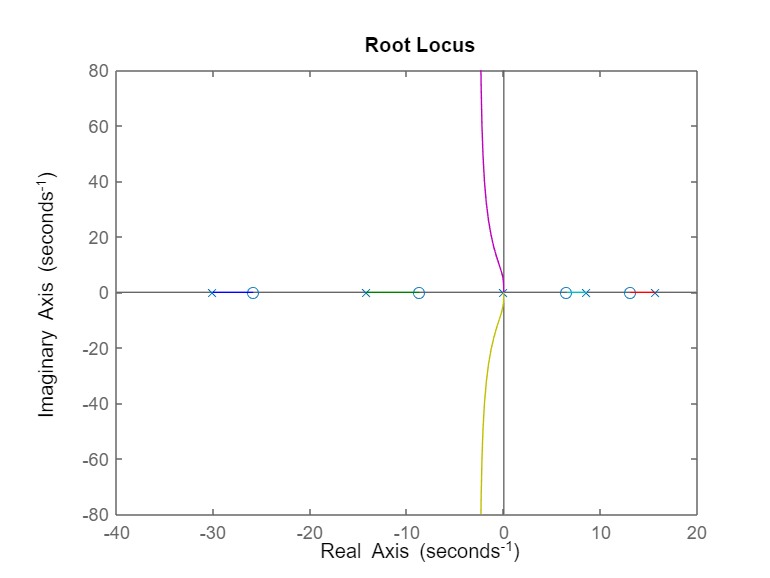

olsys = ss(A0_real,B0_real,C,D);
s = tf('s');
oltf = C*inv(s*eye(6) - A0_real)*B0_real;
rlocus(olsys(1))

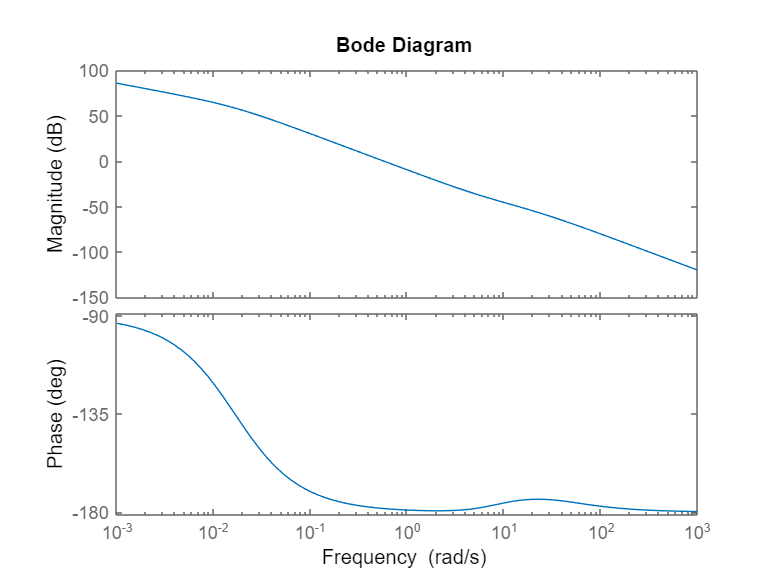

bode(olsys(1))

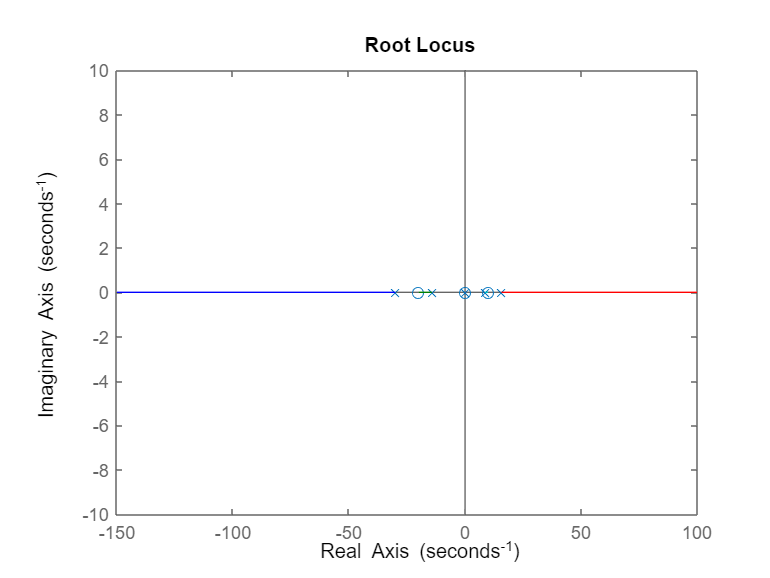

rlocus(olsys(2))

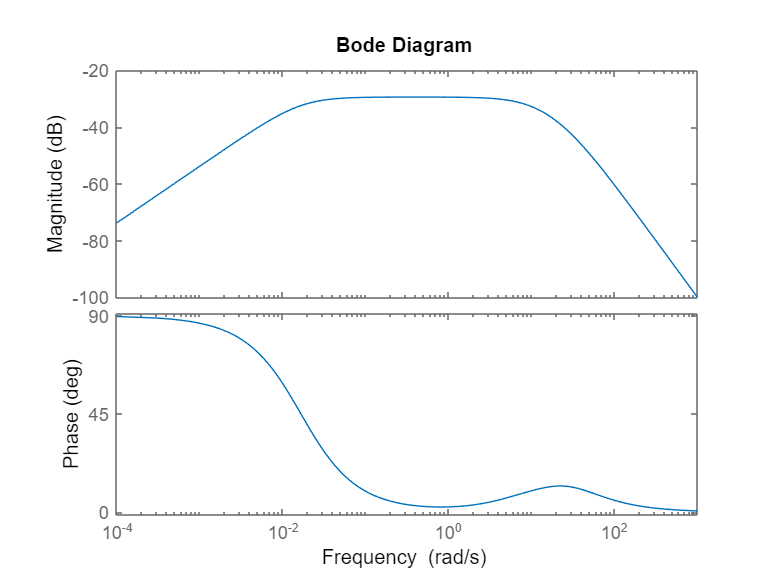

bode(olsys(2))

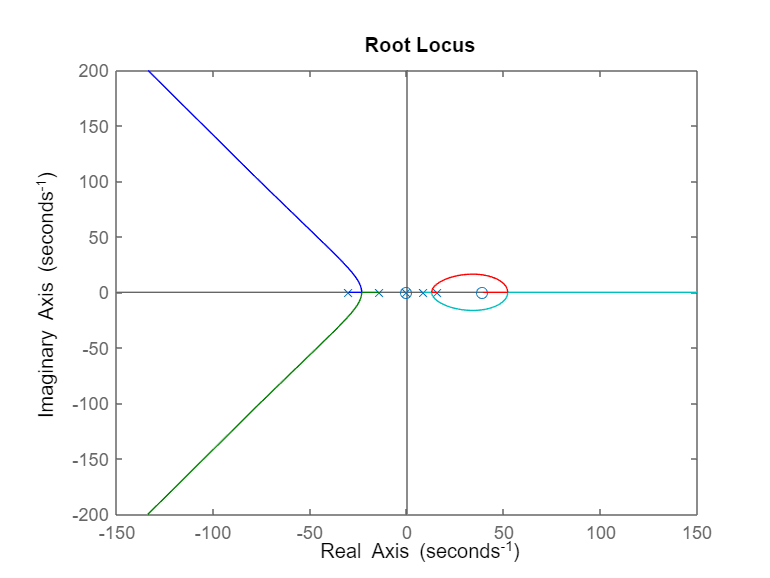

rlocus(olsys(3))

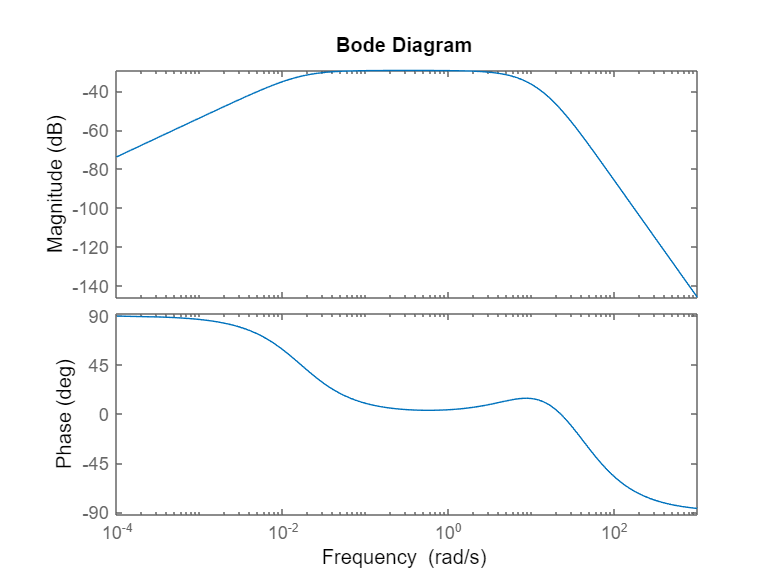

bode(olsys(3))

### Stabilizing the System with Proportional Gain Feedback

% placing poles with 4 poles optimally damped and 1 set of poles critically damped
% speed of the poles chosen to balance damping with speed
p = [-5, -5, -10*(1 + 1i*[1, -1]), -10.6*(1 + 1i*[1, -1])];
gains = acker(A0_real,B0_real,p)

gains =    58.4965 -197.6694  286.9746   39.1935    0.8044   14.8938


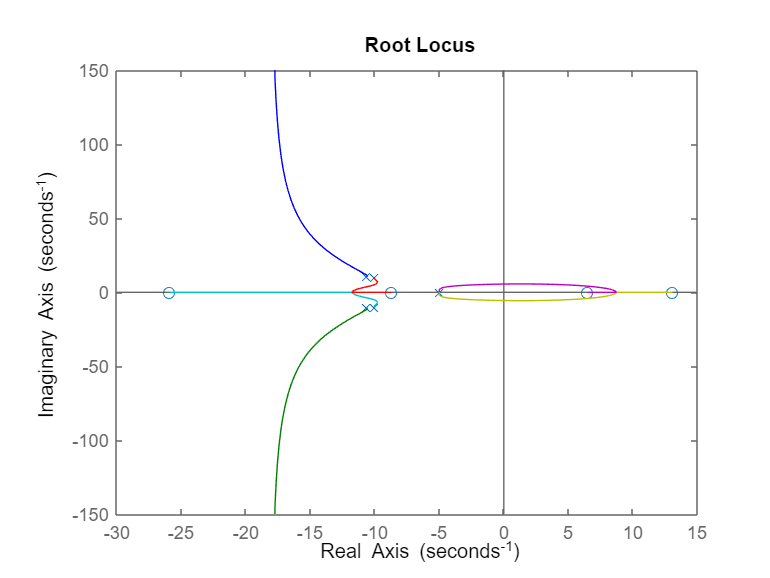

% u = -Kx + r => xdot = (A - B*K)*x + B*r
Abar = A0_real-B0_real*gains;
% Closed Loop system
states = {'x' 'theta_1' 'theta_1' 'x_dot' 'theta_dot_1' 'theta_dot_2'};
inputs = {'u'};
outputs = {'x'; 'theta_1'; 'theta_2'};
clsys = ss(Abar,B0_real,C,D,'statename',states,'inputname',inputs,'outputname',outputs);
rlocus(clsys(1))

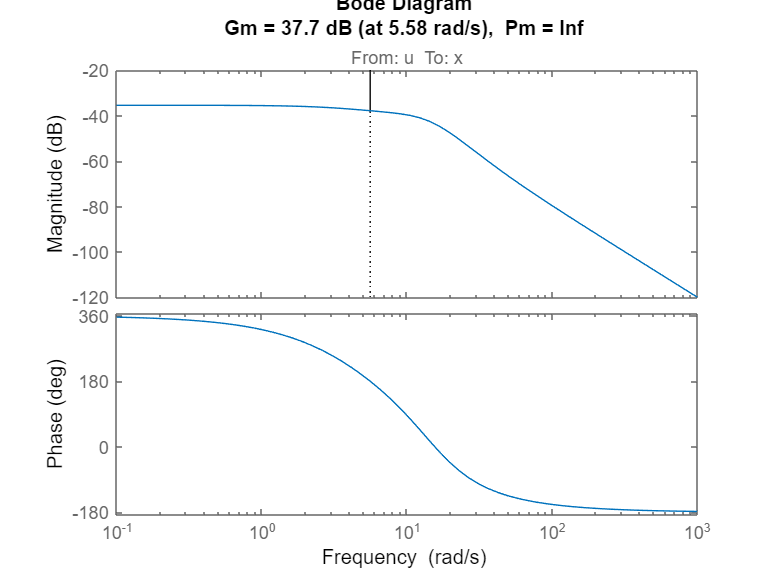

margin(clsys(1))

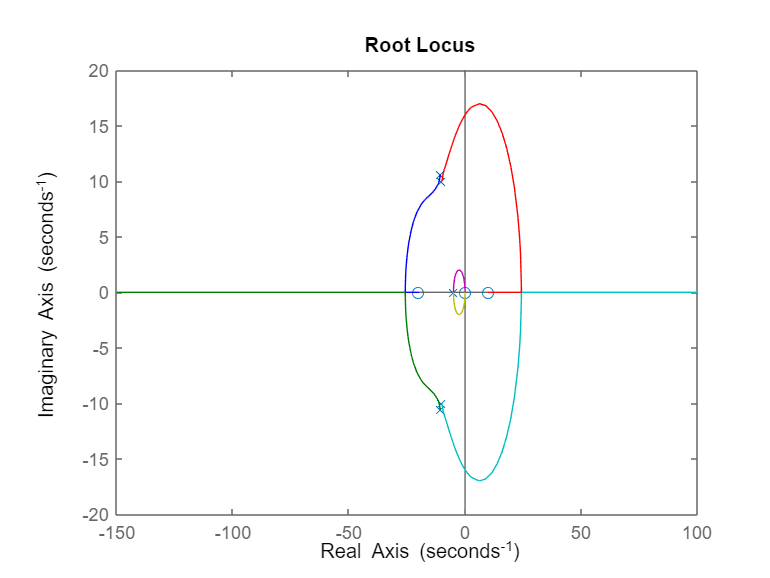

rlocus(clsys(2))

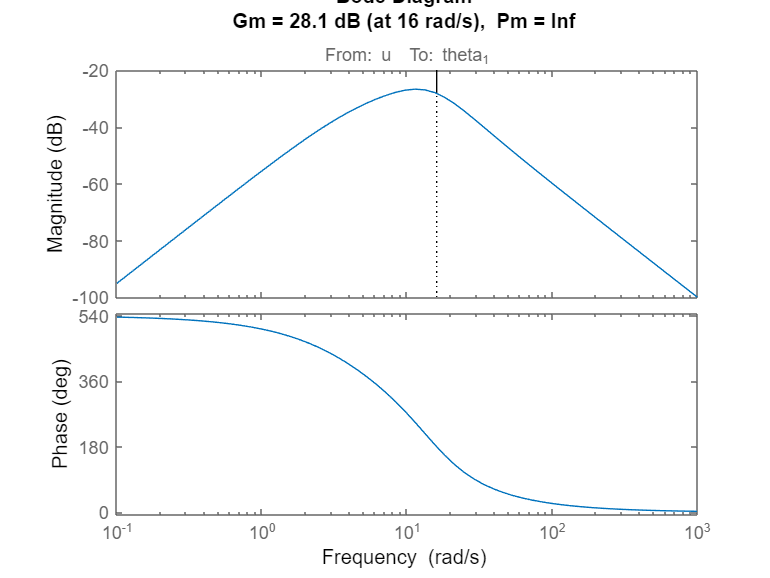

margin(clsys(2))

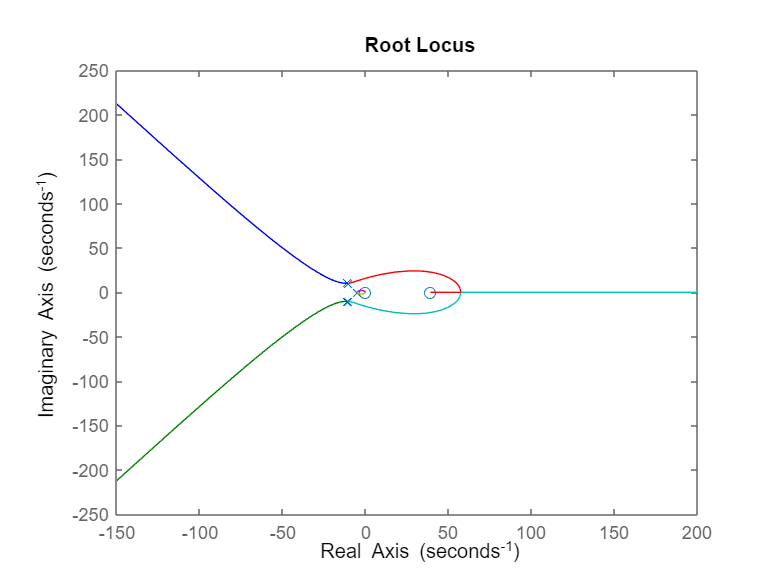

rlocus(clsys(3))

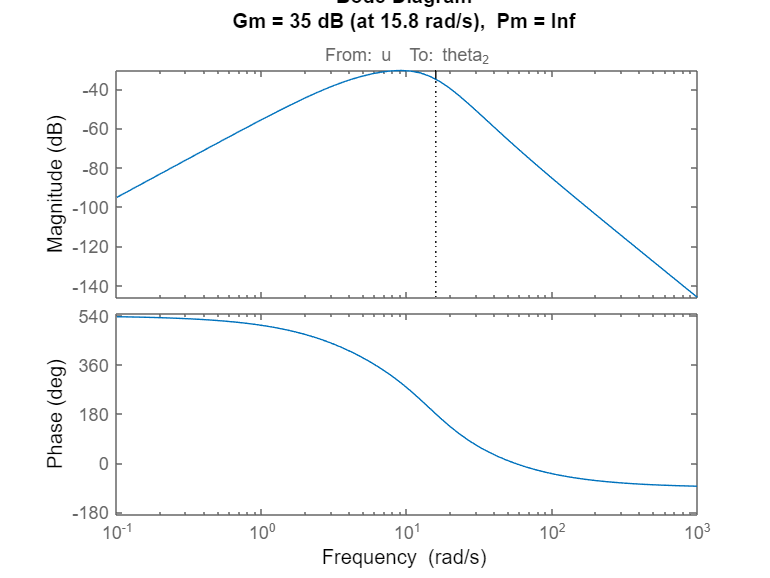

margin(clsys(3))

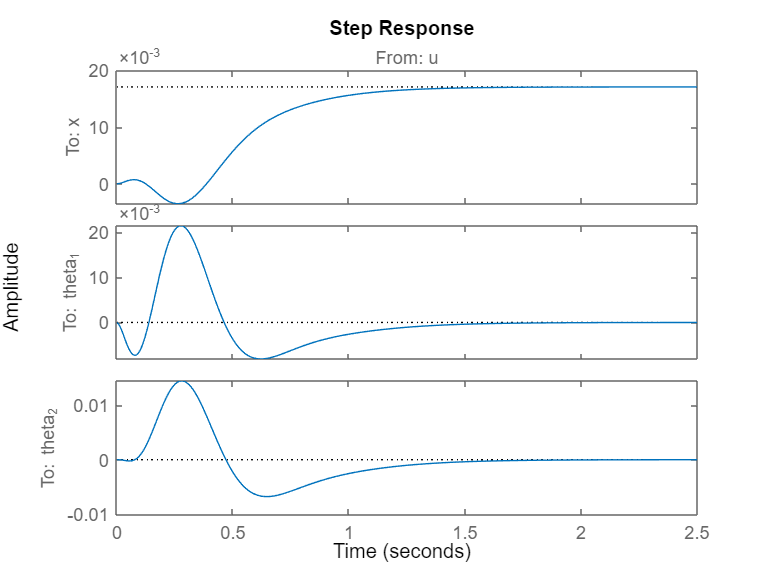

step(clsys)

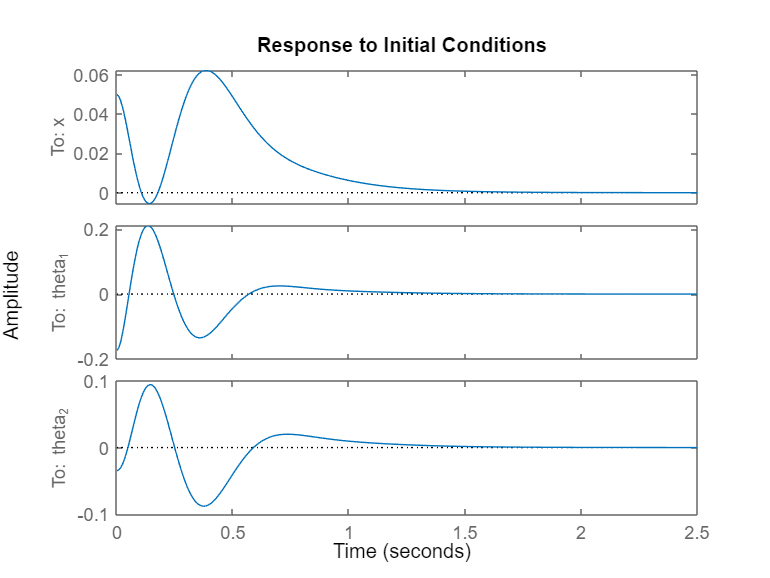

initial(clsys,[0.05; -10*pi/180; -2*pi/180; 0; 0; 0])

### Iterating Through Ratios of Length to discover patterns

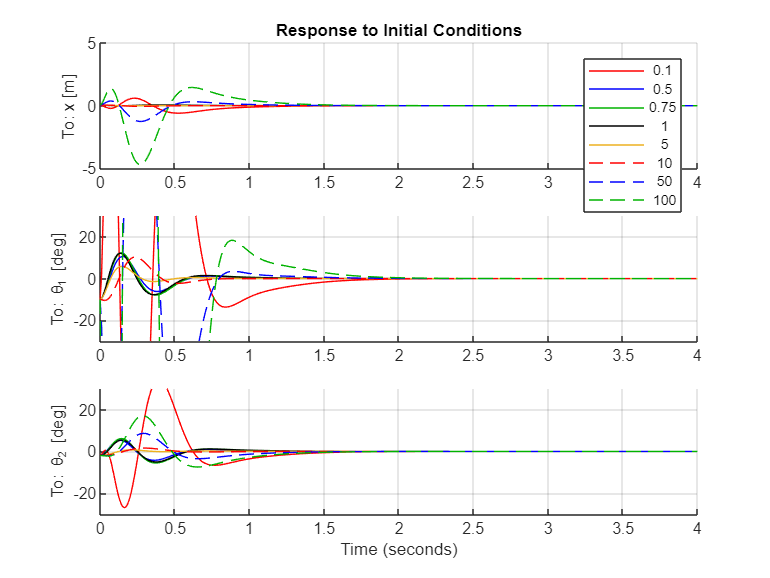

% [1/s] friction damping coefficient
k = [0.1, 0.5, 0.75, 1, 5, 10, 50, 100]; % logspace(-2,3,10);
l2_iter = k*l1; % [m]
vars_iter = zeros(size(vars,1), size(vars,2),length(k));
A0_iter = zeros(6,6,length(k));
B0_iter = zeros(6,1,length(k));
gains = zeros(1,6,length(k));
Abar = zeros(size(A0_iter));
t = 0:0.01:4;
states = {'x' 'theta_1' 'theta_1' 'x_dot' 'theta_dot_1' 'theta_dot_2'};
inputs = {'u'};
outputs = {'x'; 'theta_1'; 'theta_2'};
clear clsys_iter
for i = 1:length(k)
    vars_iter(:,:,i) = [d0_real, d1_real, d2_real, g_real, l1_real, l2_iter(i), m1_real, m2_real, m_q_real];
    A0_iter(:,:,i) = double(subs(A0,vars,vars_iter(:,:,i)));
    B0_iter(:,:,i) = double(subs(B0,vars,vars_iter(:,:,i)));
    % placing poles at the same locations... will see if that has an effect
    gains(:,:,i) = acker(A0_iter(:,:,i),B0_iter(:,:,i),p);
    % u = -Kx + r => xdot = (A - B*K)*x + B*r
    Abar(:,:,i) = A0_iter(:,:,i)-B0_iter(:,:,i)*gains(:,:,i);
    % Closed Loop system
    clsys_iter(:,:,i) = ss(Abar(:,:,i),B0_iter(:,:,i),C,D,'statename',states,'inputname',inputs,'outputname',outputs);
    [y(:,:,i), ~, x_iter(:,:,i)] = initial(clsys_iter(:,:,i),[0.05; -10*pi/180; -2*pi/180; 0; 0; 0],t);
end

%%

figure(20);
tiledlayout(3,1);
ax1 = nexttile; hold on; grid on;
ax1.ColorOrder = [1 0 0; 0 0 1; 0 0.7 0; 0 0 0; 0.929 0.694 0.125];
ax1.LineStyleOrder = {'-','--'};
ax2 = nexttile; hold on; grid on;
ax2.ColorOrder = [1 0 0; 0 0 1; 0 0.7 0; 0 0 0; 0.929 0.694 0.125];
ax2.LineStyleOrder = {'-','--'};
ax3 = nexttile; hold on; grid on;
ax3.ColorOrder = [1 0 0; 0 0 1; 0 0.7 0; 0 0 0; 0.929 0.694 0.125];
ax3.LineStyleOrder = {'-','--'};
title(ax1,'Response to Initial Conditions');
ylabel(ax1,'To: x [m]');
ylabel(ax2,'To: \theta_1 [deg]');
ylabel(ax3,'To: \theta_2 [deg]'); xlabel('Time (seconds)');
for i = 1:length(k)
    plot(ax1,t, y(:,1,i)); 
    
    plot(ax2,t,y(:,2,i)*180/pi); 

    plot(ax3,t,y(:,3,i)*180/pi); 

end
maxmin = 5;
degmax = 30;
ylim(ax1,[-1,1]*maxmin)
ylim(ax2,[-1 1]*degmax)
ylim(ax3,[-1 1]*degmax)
axes(ax1)
legend(num2str(k'))

## Conclusion

Holding all other variables constant, based on the above plots we can see that the ratio of the lengths of the poles begins to cause displacements of the system that are un-recoverable, if the ratio drops below 0.5 or above 10 (given our coarse iteration on the pole ratio). Our linearization of the equations of motions begin to significantly break down above approx. +/-20 deg, thus any ratio of the poles that generates rotation above 20 deg cannot be trusted. Not to mention whether the input forces required for these system responses are achievable, which I have not plotted here. 

Note that in this particular examination we have set the intiial conditions of the cart to be:

[0.05; -10*pi/180; -2*pi/180; 0; 0; 0] = $[q, \theta_1, \theta_2, \dot{q}, \dot{\theta_1}, \dot{\theta_2}]$